# Keyword Spotting in Noise Using MFCC and LSTM Networks

This example shows how to identify a keyword in noisy speech using a deep learning network. In particular, the example uses a Bidirectional Long Short-Term Memory (BiLSTM) network and mel frequency cepstral coefficients (MFCC).

## Introduction

Keyword spotting (KWS) is an essential component of voice-assist technologies, where the user speaks a predefined keyword to wake-up a system before speaking a complete command or query to the device.

This example trains a KWS deep network with feature sequences of mel-frequency cepstral coefficients (MFCC). The example also demonstrates how network accuracy in a noisy environment can be improved using data augmentation.

This example uses long short-term memory (LSTM) networks, which are a type of recurrent neural network (RNN) well-suited to study sequence and time-series data. An LSTM network can learn long-term dependencies between time steps of a sequence. An LSTM layer ([lstmLayer](docid:nnet_ref#mw_9f7c5f93-4bf2-4ddb-b922-b1c122668b9a)) can look at the time sequence in the forward direction, while a bidirectional LSTM layer ([`blstmLayer`](docid:nnet_ref#mw_8511c52b-8f87-4919-8cf9-5bc952a6ed99)) can look at the time sequence in both forward and backward directions. This example uses a bidirectional LSTM layer.

The example uses the google Speech Commands Dataset to train the deep learning model. To run the example, you must first download the data set. If you do not want to download the data set or train the network, then you can download and use a pretrained network by opening this example in MATLAB® and running the **Spot Keyword with Pretrained Network** section.

## Spot Keyword with Pretrained Network

Before going into the training process in detail, you will download and use a pretrained keyword spotting network to identify a keyword.

In this example, the keyword to spot is **YES**.

Read a test signal where the keyword is uttered.

[audioIn,fs] = audioread("keywordTestSignal.wav");
sound(audioIn,fs)

Download and load the pretrained network, the mean (M) and standard deviation (S) vectors used for feature normalization, as well as 2 audio files used for validating the network later in the example. 

downloadFolder = matlab.internal.examples.downloadSupportFile("audio","KeywordSpotting.zip");
dataFolder = tempdir;
unzip(downloadFolder,dataFolder)
netFolder = fullfile(dataFolder,"KeywordSpotting");
load(fullfile(netFolder,"KWSNet.mat"));

Create an [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) object to perform feature extraction.

windowLength = 512;
overlapLength = 384;
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hann(windowLength,"periodic"),OverlapLength=overlapLength, ...
    mfcc=true,mfccDelta=true,mfccDeltaDelta=true);

Extract features from the test signal and normalize them.

features = extract(afe,audioIn);

features = (features - M)./S;

Compute the keyword spotting binary mask. A mask value of one corresponds to a segment where the keyword was spotted.

mask = classify(KWSNet,features.');

Each sample in the mask corresponds to 128 samples from the speech signal (`windowLength ``- ``overlapLength`).

Expand the mask to the length of the signal.

mask = repmat(mask,windowLength-overlapLength,1);
mask = double(mask) - 1;
mask = mask(:);

Plot the test signal and the mask.

figure
audioIn = audioIn(1:length(mask));
t = (0:length(audioIn)-1)/fs;
plot(t,audioIn)
grid on
hold on
plot(t, mask)
legend("Speech","YES")

Listen to the spotted keyword.

sound(audioIn(mask==1),fs)

## Detect Commands Using Streaming Audio from Microphone

Test your pre-trained command detection network on streaming audio from your microphone. Try saying random words, including the keyword (**YES**).

Call [generateMATLABFunction](docid:audio_ref#mw_09903892-0161-41e5-abc3-9785cd4261e1) on the `audioFeatureExtractor` object to create the feature extraction function. You will use this function in the processing loop.

generateMATLABFunction(afe,"generateKeywordFeatures",IsStreaming=true);

Define an audio device reader that can read audio from your microphone. Set the frame length to the hop length. This enables you to compute a new set of features for every new audio frame from the microphone.

hopLength = windowLength - overlapLength;
frameLength = hopLength;
adr = audioDeviceReader(SampleRate=fs,SamplesPerFrame=frameLength);

Create a scope for visualizing the speech signal and the estimated mask.

scope = timescope(SampleRate=fs, ...
    TimeSpanSource="property", ...
    TimeSpan=5, ...
    TimeSpanOverrunAction="Scroll", ...
    BufferLength=fs*5*2, ...
    ShowLegend=true, ...
    ChannelNames={'Speech','Keyword Mask'}, ...
    YLimits=[-1.2,1.2], ...
    Title="Keyword Spotting");

Define the rate at which you estimate the mask. You will generate a mask once every `numHopsPerUpdate` audio frames.

numHopsPerUpdate = 16;

Initialize a buffer for the audio.

dataBuff = dsp.AsyncBuffer(windowLength);

Initialize a buffer for the computed features.

featureBuff = dsp.AsyncBuffer(numHopsPerUpdate);

Initialize a buffer to manage plotting the audio and the mask.

plotBuff = dsp.AsyncBuffer(numHopsPerUpdate*windowLength);

To run the loop indefinitely, set timeLimit to `Inf`. To stop the simulation, close the scope.

timeLimit = 20;

tic
while toc < timeLimit

    data = adr();
    write(dataBuff,data);
    write(plotBuff,data);

    frame = read(dataBuff,windowLength,overlapLength);
    features = generateKeywordFeatures(frame,fs);
    write(featureBuff,features.');

    if featureBuff.NumUnreadSamples == numHopsPerUpdate
        featureMatrix = read(featureBuff);
        featureMatrix(~isfinite(featureMatrix)) = 0;
        featureMatrix = (featureMatrix - M)./S;

        [keywordNet,v] = classifyAndUpdateState(KWSNet,featureMatrix.');
        v = double(v) - 1;
        v = repmat(v,hopLength,1);
        v = v(:);
        v = mode(v);
        v = repmat(v,numHopsPerUpdate*hopLength,1);

        data = read(plotBuff);
        scope([data,v]);

        if ~isVisible(scope)
            break;
        end
    end
end
hide(scope)

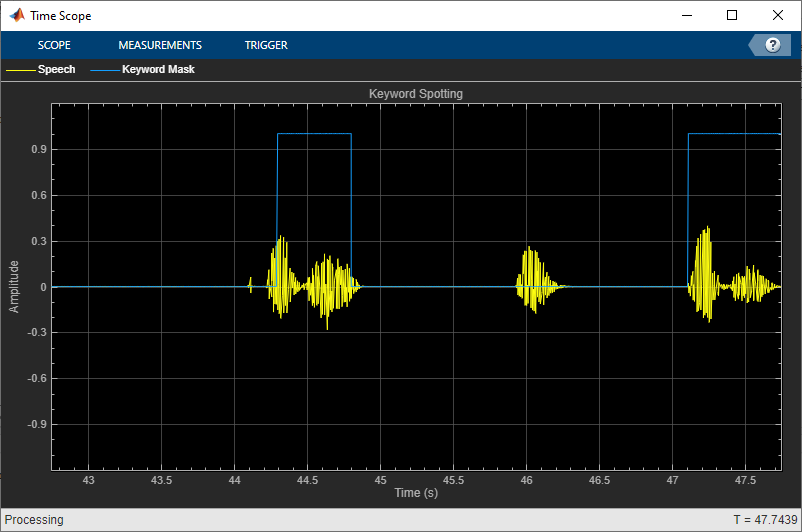

In the rest of the example, you will learn how to train the keyword spotting network.

## Training Process Summary

The training process goes through the following steps:

- Inspect a "gold standard" keyword spotting baseline on a validation signal.

- Create training utterances from a noise-free dataset.

- Train a keyword spotting LSTM network using MFCC sequences extracted from those utterances.

- Check the network accuracy by comparing the validation baseline to the output of the network when applied to the validation signal.

- Check the network accuracy for a validation signal corrupted by noise.

- Augment the training dataset by injecting noise to the speech data using [`audioDataAugmenter`](docid:audio_ref#mw_17a0d8a0-7ba7-4400-a3f3-2b63eaa6df23).

- Retrain the network with the augmented dataset.

- Verify that the retrained network now yields higher accuracy when applied to the noisy validation signal. 

## Inspect the Validation Signal

You use a sample speech signal to validate the KWS network. The validation signal consists 34 seconds of speech with the keyword **YES** appearing intermittently.

Load the validation signal.

[audioIn,fs] = audioread(fullfile(netFolder,"KeywordSpeech-16-16-mono-34secs.flac"));

Listen to the signal.

sound(audioIn,fs)

Visualize the signal.

figure
t = (1/fs)*(0:length(audioIn)-1);
plot(t,audioIn);
grid on
xlabel("Time (s)")
title("Validation Speech Signal")

## Inspect the KWS Baseline

Load the KWS baseline. This baseline was obtained using [`speech2text`](https://www.mathworks.com/matlabcentral/fileexchange/65266-speech2text) and [Signal Labeler](docid:signal_ref#mw_cecb4589-4122-4388-95da-2a5796c6e3e2). For a related example, see [Label Spoken Words in Audio Signals](docid:signal_ug#mw_8823bb48-e921-4d12-a69f-00bd24dd802c).

load("KWSBaseline.mat","KWSBaseline")

The baseline is a logical vector of the same length as the validation audio signal. Segments in `audioIn` where the keyword is uttered are set to one in `KWSBaseline`.

Visualize the speech signal along with the KWS baseline.

fig = figure;
plot(t,[audioIn,KWSBaseline'])
grid on
xlabel("Time (s)")
legend("Speech","KWS Baseline",Location="southeast")
l = findall(fig,"type","line");
l(1).LineWidth = 2;
title("Validation Signal")

Listen to the speech segments identified as keywords.

sound(audioIn(KWSBaseline),fs)

The objective of the network that you train is to output a KWS mask of zeros and ones like this baseline.

## Load Speech Commands Data Set

Download and extract the Google Speech Commands Dataset [1].

downloadFolder = matlab.internal.examples.downloadSupportFile("audio","google_speech.zip");
dataFolder = tempdir;
unzip(downloadFolder,dataFolder)
dataset = fullfile(dataFolder,"google_speech");

Create an [`audioDatastore`](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) that points to the data set.

ads = audioDatastore(dataset,LabelSource="foldername",Includesubfolders=true);
ads = shuffle(ads);

The dataset contains background noise files that are not used in this example. Use [`subset`](docid:audio_ref#mw_6823f1d7-3610-4d7d-89d0-816746a24ca9) to create a new datastore that does not have the background noise files.

isBackNoise = ismember(ads.Labels,"background");
ads = subset(ads,~isBackNoise);

The dataset has approximately 65,000 one-second long utterances of 30 short words (including the keyword YES). Get a breakdown of the word distribution in the datastore.

countEachLabel(ads)

Split `ads` into two datastores: The first datastore contains files corresponding to the keyword. The second datastore contains all the other words.

keyword = "yes";
isKeyword = ismember(ads.Labels,keyword);
adsKeyword = subset(ads,isKeyword);
adsOther = subset(ads,~isKeyword);

To train the network with the entire dataset and achieve the highest possible accuracy, set `speedupExample` to `false`. To run this example quickly, set `speedupExample` to `true`.

speedupExample = false;
if speedupExample
    % Reduce the dataset by a factor of 20
    adsKeyword = splitEachLabel(adsKeyword,round(numel(adsKeyword.Files)/20));
    numUniqueLabels = numel(unique(adsOther.Labels));
    adsOther = splitEachLabel(adsOther,round(numel(adsOther.Files)/numUniqueLabels/20));
end

Get a breakdown of the word distribution in each datastore. Shuffle the adsOther datastore so that consecutive reads return different words.

countEachLabel(adsKeyword)
countEachLabel(adsOther)
adsOther = shuffle(adsOther);

## Create Training Sentences and Labels

The training datastores contain one-second speech signals where one word is uttered. You will create more complex training speech utterances that contain a mixture of the keyword along with other words. 

Here is an example of a constructed utterance. Read one keyword from the keyword datastore and normalize it to have a maximum value of one.

yes = read(adsKeyword);
yes = yes/max(abs(yes));

The signal has non-speech portions (silence, background noise, etc.) that do not contain useful speech information. This example removes silence using [detectSpeech](docid:audio_ref#mw_f7b40697-af02-4c71-a508-ecd8f7f47400).

Get the start and end indices of the useful portion of the signal.

speechIndices = detectSpeech(yes,fs);

Randomly select the number of words to use in the synthesized training sentence. Use a maximum of 10 words.

numWords = randi([0,10]);

Randomly pick the location at which the keyword occurs.

keywordLocation = randi([1,numWords+1]);

Read the desired number of non-keyword utterances, and construct the training sentence and mask.

sentence = [];
mask = [];
for index = 1:numWords+1
    if index == keywordLocation
        sentence = [sentence;yes]; %#ok
        newMask = zeros(size(yes));
        newMask(speechIndices(1,1):speechIndices(1,2)) = 1;
        mask = [mask;newMask]; %#ok
    else
        other = read(adsOther);
        other = other./max(abs(other));
        sentence = [sentence;other]; %#ok
        mask = [mask;zeros(size(other))]; %#ok
    end
end

Plot the training sentence along with the mask.

figure
t = (1/fs)*(0:length(sentence)-1);
fig = figure;
plot(t,[sentence,mask])
grid on
xlabel("Time (s)")
legend("Training Signal","Mask",Location="southeast")
l = findall(fig,"type","line");
l(1).LineWidth = 2;
title("Example Utterance")

Listen to the training sentence.

sound(sentence,fs)

## Extract Features

This example trains a deep learning network using 39 MFCC coefficients (13 MFCC, 13 delta and 13 delta-delta coefficients).

Define parameters required for MFCC extraction.

windowLength = 512;
overlapLength = 384;

Create an `audioFeatureExtractor` object to perform the feature extraction.

afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hann(windowLength,"periodic"),OverlapLength=overlapLength, ...
    mfcc=true,mfccDelta=true,mfccDeltaDelta=true);

Extract the features.

featureMatrix = extract(afe,sentence);
size(featureMatrix)

Note that you compute MFCC by sliding a window through the input, so the feature matrix is shorter than the input speech signal. Each row in `featureMatrix` corresponds to 128 samples from the speech signal (`windowLength ``- ``overlapLength`).

Compute a mask of the same length as `featureMatrix`.

hopLength = windowLength - overlapLength;
range = hopLength*(1:size(featureMatrix,1)) + hopLength;
featureMask = zeros(size(range));
for index = 1:numel(range)
    featureMask(index) = mode(mask((index-1)*hopLength+1:(index-1)*hopLength+windowLength));
end

## Extract Features from Training Dataset

Sentence synthesis and feature extraction for the whole training dataset can be quite time-consuming. To speed up processing, if you have Parallel Computing Toolbox™, partition the training datastore, and process each partition on a separate worker. 

Select a number of datastore partitions.

numPartitions = 6;

Initialize cell arrays for the feature matrices and masks.

TrainingFeatures = {};
TrainingMasks= {};

Perform sentence synthesis, feature extraction, and mask creation using `parfor`.

emptyCategories = categorical([1 0]);
emptyCategories(:) = [];

tic
parfor ii = 1:numPartitions

    subadsKeyword = partition(adsKeyword,numPartitions,ii);
    subadsOther = partition(adsOther,numPartitions,ii);

    count = 1;
    localFeatures = cell(length(subadsKeyword.Files),1);
    localMasks = cell(length(subadsKeyword.Files),1);

    while hasdata(subadsKeyword)

        % Create a training sentence
        [sentence,mask] = synthesizeSentence(subadsKeyword,subadsOther,fs,windowLength);

        % Compute mfcc features
        featureMatrix = extract(afe, sentence);
        featureMatrix(~isfinite(featureMatrix)) = 0;

        % Create mask
        range = hopLength*(1:size(featureMatrix,1)) + hopLength;
        featureMask = zeros(size(range));
        for index = 1:numel(range)
            featureMask(index) = mode(mask((index-1)*hopLength+1:(index-1)*hopLength+windowLength));
        end

        localFeatures{count} = featureMatrix;
        localMasks{count} = [emptyCategories,categorical(featureMask)];

        count = count + 1;
    end

    TrainingFeatures = [TrainingFeatures;localFeatures];
    TrainingMasks = [TrainingMasks;localMasks];
end
disp("Training feature extraction took " + toc + " seconds.")

It is good practice to normalize all features to have zero mean and unity standard deviation. Compute the mean and standard deviation for each coefficient and use them to normalize the data.

sampleFeature = TrainingFeatures{1};
numFeatures = size(sampleFeature,2);
featuresMatrix = cat(1,TrainingFeatures{:});
if speedupExample
    load(fullfile(netFolder,"keywordNetNoAugmentation.mat"),"keywordNetNoAugmentation","M","S");
else
    M = mean(featuresMatrix);
    S = std(featuresMatrix);
end
for index = 1:length(TrainingFeatures)
    f = TrainingFeatures{index};
    f = (f - M)./S;
    TrainingFeatures{index} = f.'; %#ok
end

## Extract Validation Features

Extract MFCC features from the validation signal.

featureMatrix = extract(afe, audioIn);
featureMatrix(~isfinite(featureMatrix)) = 0;

Normalize the validation features.

FeaturesValidationClean = (featureMatrix - M)./S;
range = hopLength*(1:size(FeaturesValidationClean,1)) + hopLength;

Construct the validation KWS mask.

featureMask = zeros(size(range));
for index = 1:numel(range)
    featureMask(index) = mode(KWSBaseline((index-1)*hopLength+1:(index-1)*hopLength+windowLength));
end
BaselineV = categorical(featureMask);

## Define the LSTM Network Architecture

LSTM networks can learn long-term dependencies between time steps of sequence data. This example uses the bidirectional LSTM layer [`bilstmLayer`](docid:nnet_ref#mw_8511c52b-8f87-4919-8cf9-5bc952a6ed99) to look at the sequence in both forward and backward directions.

Specify the input size to be sequences of size `numFeatures`. Specify two hidden bidirectional LSTM layers with an output size of 150 and output a sequence. This command instructs the bidirectional LSTM layer to map the input time series into 150 features that are passed to the next layer. Specify two classes by including a fully connected layer of size 2, followed by a softmax layer and a classification layer.

layers = [ ...
    sequenceInputLayer(numFeatures)
    bilstmLayer(150,OutputMode="sequence")
    bilstmLayer(150,OutputMode="sequence")
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
    ];

## Define Training Options

Specify the training options for the classifier. Set `MaxEpochs` to 10 so that the network makes 10 passes through the training data. Set `MiniBatchSize` to  `64` so that the network looks at 64 training signals at a time. Set `Plots` to `"training-progress"` to generate plots that show the training progress as the number of iterations increases. Set `Verbose` to `false` to disable printing the table output that corresponds to the data shown in the plot. Set `Shuffle` to `"every-epoch"` to shuffle the training sequence at the beginning of each epoch. Set `LearnRateSchedule` to `"piecewise"` to decrease the learning rate by a specified factor (0.1) every time a certain number of epochs (5) has passed. Set `ValidationData` to the validation predictors and targets.

This example uses the adaptive moment estimation (ADAM) solver. ADAM performs better with recurrent neural networks (RNNs) like LSTMs than the default stochastic gradient descent with momentum (SGDM) solver.

maxEpochs = 10;
miniBatchSize = 64;
options = trainingOptions("adam", ...
    InitialLearnRate=1e-4, ...
    MaxEpochs=maxEpochs, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Verbose=false, ...
    ValidationFrequency=floor(numel(TrainingFeatures)/miniBatchSize), ...
    ValidationData={FeaturesValidationClean.',BaselineV}, ...
    Plots="training-progress", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=5);

## Train the LSTM Network

Train the LSTM network with the specified training options and layer architecture using [`trainNetwork`](docid:nnet_ref#bu6sn4c). Because the training set is large, the training process can take several minutes.

[keywordNetNoAugmentation,netInfo] = trainNetwork(TrainingFeatures,TrainingMasks,layers,options);
if speedupExample
    load(fullfile(netFolder,"keywordNetNoAugmentation.mat"),"keywordNetNoAugmentation","M","S");
end

## Check Network Accuracy for Noise-Free Validation Signal

Estimate the KWS mask for the validation signal using the trained network. 

v = classify(keywordNetNoAugmentation,FeaturesValidationClean.');

Calculate and plot the validation confusion matrix from the vectors of actual and estimated labels.

figure
confusionchart(BaselineV,v, ...
    Title="Validation Accuracy", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

Convert the network output from categorical to double.

v = double(v) - 1;
v = repmat(v,hopLength,1);
v = v(:);

Listen to the keyword areas identified by the network.

sound(audioIn(logical(v)),fs)

Visualize the estimated and expected KWS masks.

baseline = double(BaselineV) - 1;
baseline = repmat(baseline,hopLength,1);
baseline = baseline(:);

t = (1/fs)*(0:length(v)-1);
fig = figure;
plot(t,[audioIn(1:length(v)),v,0.8*baseline])
grid on
xlabel("Time (s)")
legend("Training Signal","Network Mask","Baseline Mask",Location="southeast")
l = findall(fig,"type","line");
l(1).LineWidth = 2;
l(2).LineWidth = 2;
title("Results for Noise-Free Speech")

## Check Network Accuracy for a Noisy Validation Signal

You will now check the network accuracy for a noisy speech signal. The noisy signal was obtained by corrupting the clean validation signal by additive white Gaussian noise.

Load the noisy signal.

[audioInNoisy,fs] = audioread(fullfile(netFolder,"NoisyKeywordSpeech-16-16-mono-34secs.flac"));
sound(audioInNoisy,fs)

Visualize the signal.

figure
t = (1/fs)*(0:length(audioInNoisy)-1);
plot(t,audioInNoisy)
grid on
xlabel("Time (s)")
title("Noisy Validation Speech Signal")

Extract the feature matrix from the noisy signal.

featureMatrixV = extract(afe, audioInNoisy);
featureMatrixV(~isfinite(featureMatrixV)) = 0;
FeaturesValidationNoisy = (featureMatrixV - M)./S;

Pass the feature matrix to the network.

v = classify(keywordNetNoAugmentation,FeaturesValidationNoisy.');

Compare the network output to the baseline. Note that the accuracy is lower than the one you got for a clean signal.

figure
confusionchart(BaselineV,v, ...
    Title="Validation Accuracy - Noisy Speech", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

Convert the network output from categorical to double.

v = double(v) - 1;
v = repmat(v,hopLength,1);
v = v(:);

Listen to the keyword areas identified by the network.

sound(audioIn(logical(v)),fs)

Visualize the estimated and baseline masks.

t = (1/fs)*(0:length(v)-1);
fig = figure;
plot(t,[audioInNoisy(1:length(v)),v,0.8*baseline])
grid on
xlabel("Time (s)")
legend("Training Signal","Network Mask","Baseline Mask",Location="southeast")
l = findall(fig,"type","line");
l(1).LineWidth = 2;
l(2).LineWidth = 2;
title("Results for Noisy Speech - No Data Augmentation")

## Perform Data Augmentation

The trained network did not perform well on a noisy signal because the trained dataset contained only noise-free sentences. You will rectify this by augmenting your dataset to include noisy sentences.

Use [`audioDataAugmenter`](docid:audio_ref#mw_17a0d8a0-7ba7-4400-a3f3-2b63eaa6df23) to augment your dataset.

ada = audioDataAugmenter(TimeStretchProbability=0,PitchShiftProbability=0, ...
    VolumeControlProbability=0,TimeShiftProbability=0, ...
    SNRRange=[-1,1],AddNoiseProbability=0.85);

With these settings, the `audioDataAugmenter` object corrupts an input audio signal with white Gaussian noise with a probability of 85%. The SNR is randomly selected from the range [-1 1] (in dB). There is a 15% probability that the augmenter does not modify your input signal.

As an example, pass an audio signal to the augmenter.

reset(adsKeyword)
x = read(adsKeyword);
data = augment(ada,x,fs)

Inspect the `AugmentationInfo` variable in `data` to verify how the signal was modified.

data.AugmentationInfo

Reset the datastores.

reset(adsKeyword)
reset(adsOther)

Initialize the feature and mask cells.

TrainingFeatures = {};
TrainingMasks = {};

Perform feature extraction again. Each signal is corrupted by noise with a probability of 85%, so your augmented dataset has approximately 85% noisy data and 15% noise-free data.

tic
parfor ii = 1:numPartitions

    subadsKeyword = partition(adsKeyword,numPartitions,ii);
    subadsOther = partition(adsOther,numPartitions,ii);

    count = 1;
    localFeatures = cell(length(subadsKeyword.Files),1);
    localMasks = cell(length(subadsKeyword.Files),1);

    while hasdata(subadsKeyword)

        [sentence,mask] = synthesizeSentence(subadsKeyword,subadsOther,fs,windowLength);

        % Corrupt with noise
        augmentedData = augment(ada,sentence,fs);
        sentence = augmentedData.Audio{1};

        % Compute mfcc features
        featureMatrix = extract(afe, sentence);
        featureMatrix(~isfinite(featureMatrix)) = 0;

        range = hopLength*(1:size(featureMatrix,1)) + hopLength;
        featureMask = zeros(size(range));
        for index = 1:numel(range)
            featureMask(index) = mode(mask((index-1)*hopLength+1:(index-1)*hopLength+windowLength));
        end

        localFeatures{count} = featureMatrix;
        localMasks{count} = [emptyCategories,categorical(featureMask)];

        count = count + 1;
    end

    TrainingFeatures = [TrainingFeatures;localFeatures];
    TrainingMasks = [TrainingMasks;localMasks];
end
disp("Training feature extraction took " + toc + " seconds.")

Compute the mean and standard deviation for each coefficient; use them to normalize the data.

sampleFeature = TrainingFeatures{1};
numFeatures = size(sampleFeature,2);
featuresMatrix = cat(1,TrainingFeatures{:});
if speedupExample
    load(fullfile(netFolder,"KWSNet.mat"),"KWSNet","M","S");
else
    M = mean(featuresMatrix);
    S = std(featuresMatrix);
end
for index = 1:length(TrainingFeatures)
    f = TrainingFeatures{index};
    f = (f - M) ./ S;
    TrainingFeatures{index} = f.'; %#ok
end

Normalize the validation features with the new mean and standard deviation values.

FeaturesValidationNoisy = (featureMatrixV - M)./S;

## Retrain Network with Augmented Dataset

Recreate the training options. Use the noisy baseline features and mask for validation.

options = trainingOptions("adam", ...
    InitialLearnRate=1e-4, ...
    MaxEpochs=maxEpochs, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Verbose=false, ...
    ValidationFrequency=floor(numel(TrainingFeatures)/miniBatchSize), ...
    ValidationData={FeaturesValidationNoisy.',BaselineV}, ...
    Plots="training-progress", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.1, ...
    LearnRateDropPeriod=5);

Train the network.

[KWSNet,netInfo] = trainNetwork(TrainingFeatures,TrainingMasks,layers,options);
if speedupExample
    load(fullfile(netFolder,"KWSNet.mat"));
end

Verify the network accuracy on the validation signal.

v = classify(KWSNet,FeaturesValidationNoisy.');

Compare the estimated and expected KWS masks.

figure
confusionchart(BaselineV,v, ...
    Title="Validation Accuracy with Data Augmentation", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");

Listen to the identified keyword regions.

v = double(v) - 1;
v = repmat(v,hopLength,1);
v = v(:);

sound(audioIn(logical(v)),fs)

Visualize the estimated and expected masks.

fig = figure;
plot(t,[audioInNoisy(1:length(v)),v,0.8*baseline])
grid on
xlabel("Time (s)")
legend("Training Signal","Network Mask","Baseline Mask",Location="southeast")
l = findall(fig,"type","line");
l(1).LineWidth = 2;
l(2).LineWidth = 2;
title("Results for Noisy Speech - With Data Augmentation")

## Supporting Functions

#### Synthesize Sentence

function [sentence,mask] = synthesizeSentence(adsKeyword,adsOther,fs,minlength)

% Read one keyword
keyword = read(adsKeyword);
keyword = keyword./max(abs(keyword));

% Identify region of interest
speechIndices = detectSpeech(keyword,fs);
if isempty(speechIndices) || diff(speechIndices(1,:)) <= minlength
    speechIndices = [1,length(keyword)];
end
keyword = keyword(speechIndices(1,1):speechIndices(1,2));

% Pick a random number of other words (between 0 and 10)
numWords = randi([0,10]);
% Pick where to insert keyword
loc = randi([1,numWords+1]);
sentence = [];
mask = [];
for index = 1:numWords+1
    if index==loc
        sentence = [sentence;keyword];
        newMask = ones(size(keyword));
        mask = [mask;newMask];
    else
        other = read(adsOther);
        other = other./max(abs(other));
        sentence = [sentence;other];
        mask = [mask;zeros(size(other))];
    end
end
end

## References

[1] Warden P. "Speech Commands: A public dataset for single-word speech recognition", 2017. Available from [https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz](https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz). Copyright Google 2017. The Speech Commands Dataset is licensed under the Creative Commons Attribution 4.0 license.

*Copyright 2019-2020 The MathWorks, Inc.*